## Position Stepper Motor.mlx contains and support the LinStepperArduino() functions

This script creates the code for a set of functions to position control a Lin 4118M-01RO stepperMotor attached to a Lin R208 microstepping driver controller from two digital pins on a standard Arduino-class micro controller

- Arduino PWN pin6 to R208 step input(yellow)

- Arduino pin7 directly to dir-input(orange)

- Arduino 5V DC to 5V DC for opticle isolator (blue)

- Arduino GND to R208 logic ground(white wire)

- Use built-in LED on pin13 for blinky robot alive light

clc     %clear command window
clear   %clea MATLAB workspace

### Set up Robot control system(code runs once)

%Create arduino and arduino-pin ref objects
[robotArduino, blinkLED]=SETUPARDUINO('/dev/cu.usbmodem14101', 'Mega2560');

Warning! Downloading may take a seconds
Warning! Stepper moving!


%ACTmovesStepMotor(arduinoName, numberOfSteps, direction, speed)
pause(1.0);
beep;


ACTmoveStepMotor(robotArduino, 50, 0, 0.01)
Blink(robotArduino, blinkLED, 1);
beep;
ACTmoveStepMotor(robotArduino, 50, 0, 0.01)
Blink(robotArduino, blinkLED, 1);
beep;

%configure test loop to collect n data points.
nTest = input(['Enter number of servo test positions,' ...
    'followed by enter: ']);
%create a variable to hold experimental position data
    positionData = zeros(nTest,2);
r = rateControl(0.25);
reset(r);


### Run robot control loop(code that runs over and over)

controlFlag = 1;
oldAngle = 0;
while(controlFlag < nTest+1)
    commandAngle = SENSE();
    [steps, direction] = THINK(oldAngle, commandAngle);
    ACTmoveStepMotor(robotArduino, steps, direction, 0.1);
    oldAngle = commandAngle;

    positionData(controlFlag, 1)= input('Enter actual position degrees: ');
    positionData(controlFlag, 2)= commandAngle;
    Blink(robotArduino, blinkLED, 1);
    waitfor(r);
    controlFlag = controlFlag+1;
end

### Mission data processing

For many robot applications, you will need to post-process the data collected after the mission. Here we will plot the desired versus actual motor positions

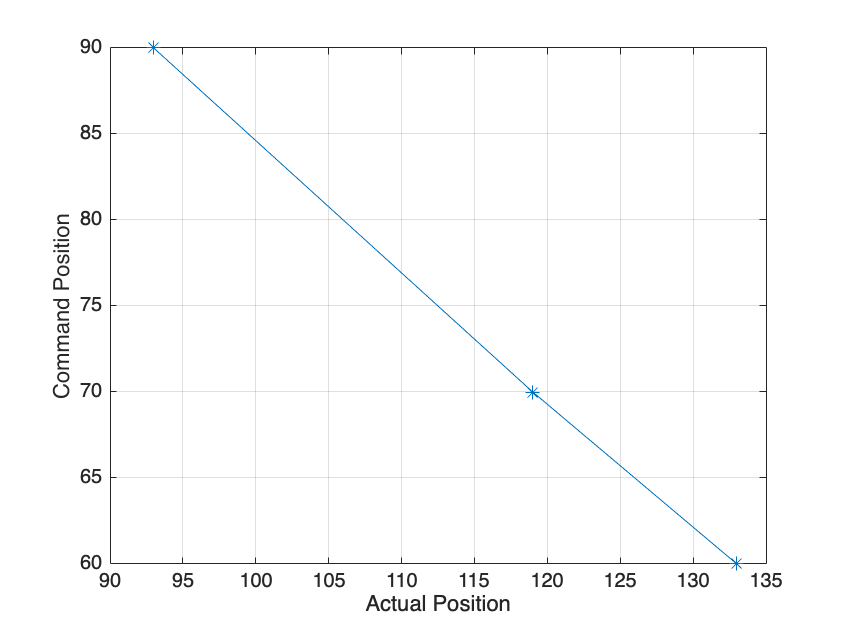

%position data vs. actual position
    plot (positionData(:,1), positionData(:,2), '-*')
    xlabel('Actual Position')
    ylabel('Command Position')
    grid

save positionServo.dat positionData -ascii

### Clean and shutdown

Finally, with most embeded robot controllers, it's good to practice to put all actuators into a safe position and then release all control objects and shutdown all communication paths. This keeps systems from jamming when you want to run again

[steps, direction]= THINK(oldAngle, 0);
ACTmoveStepMotor(robotArduino, steps, direction, 0.1);
Blink(robotArduino, blinkLED, 3);
beep;
clc
disp('Arduino stepper program has ended');

Arduino stepper program has ended


Arduino stepper program has ended

clear robotArduino
beep


### Robot Function(store this code local functions here)

In practice for modularity, readability and longitevity, your main robot code should be as brief as possible and the bulk of work should be done by functions.

function [robotArduino, blinkLED] = SETUPARDUINO(COMPORT, MODEL)
    robotArduino = arduino(COMPORT, MODEL, 'Libraries', 'I2C');
    %create a global arduino object
    disp('Warning! Downloading may take a seconds');

    blinkLED = 'D13';
    configurePin(robotArduino, blinkLED, 'DigitalOutput');
    %pin13 as LED

    stepPin = 'D6';
    configurePin(robotArduino, stepPin, 'DigitalOutput');
    %pin6 as step pulse

    dirPin = 'D7';
    configurePin(robotArduino, dirPin, 'DigitalOutput');
    %pin7 as direction control
    Blink(robotArduino, blinkLED, 3);
    disp('Warning! Stepper moving!');
    pause(3.0);
end 

function [] = Blink(a, LED, n)
    for bIndex = 1:n
        writeDigitalPin(a, LED, 0);
        pause(0.2);
        writeDigitalPin(a, LED, 1);
        pause(0.2);
    end
end

### ACT Function(store all sense related local functions here)

function [] = ACTmoveStepMotor(arduinoName, numberOfSteps, direction, speed)
%rotate stepper by numberOfSteps in direction, with puase in between
% #of steps are(0 -200) direction is (0 clockwise)(1 counterclockwise)
    stepPin = 'D6';
    dirPin = 'D7';

    writeDigitalPin(arduinoName, dirPin, direction);
    %run stepper for number of steps required at speed requested
    for mIndex = 1:numberOfSteps
        writeDigitalPin(arduinoName, stepPin, 0);
        pause(speed);
        writeDigitalPin(arduinoName, stepPin, 1);
        pause(speed);
    end
end

### Sense Function(store all sense related local functions here)

function commandAngle = SENSE()
    commandAngle = input('Enter desired servo angle in degrees: ');
end

function readAngle = SENSE2(arduinoName, readPin)
    print(readVoltage(arduinoName,readPin))

end

### Think Function(store all think related local functions here)

function [steps, direction]= THINK(oldAngle, commandAngle)
    differenceAngle = oldAngle-commandAngle;
    steps = abs(differenceAngle*0.55555);
    if (commandAngle >=oldAngle)
        direction = 1;
    else
        direction=0;
    end
end